addpath('rawData\data_1\')

load('rawData\data_1\data_1.mat');

%暂时先只处理0.01s。别忘了最终是要处理整个文件的！
seq_sur1=seq_sur(1:(length(seq_sur)/50));
seq_ref1=seq_ref(1:(length(seq_sur)/50));
duration1=0.01;
fs=f_s;

### Task 1

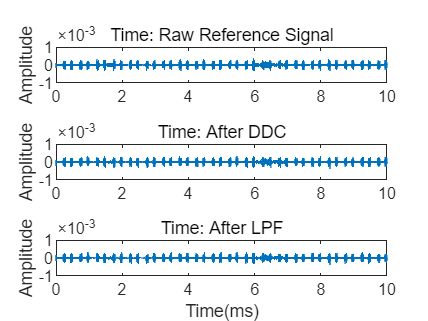

y1rd=sigAfterDDC(seq_ref1,fs);
y1rf=sigAfterLPF(seq_ref1,fs);
plotTimeSig(seq_ref1,fs,1,3,'Time: Raw Reference Signal')
plotTimeSig(y1rd,fs,2,3,'Time: After DDC')
plotTimeSig(y1rf,fs,3,3,'Time: After LPF')

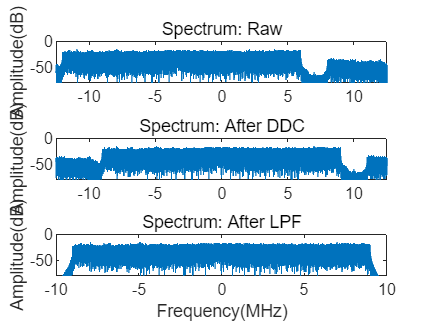


plotSpectrum(seq_ref1,fs,1,3,'Spectrum: Raw')
plotSpectrum(y1rd,fs,2,3,'Spectrum: After DDC')
plotSpectrum(y1rf,fs,3,3,'Spectrum: After LPF')

### Task 2

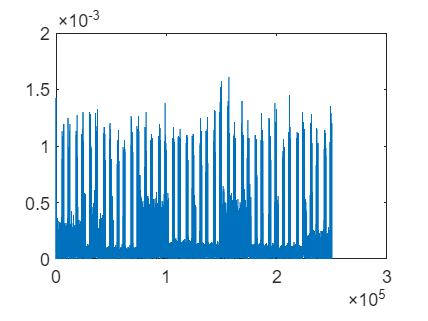

     6



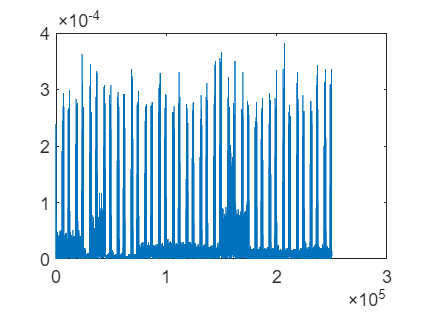

ans = 2.4991e-05

figure
cor(24*1e-8,-40,seq_sur1,seq_ref1,fs)

function Cor=cor(tau,f_D,y_surv,y_ref,fs)
    zero_compensation =zeros([1,fix(tau*fs)]);
    disp(fix(tau*fs))
    y_surv_com=[y_surv,zero_compensation];
    plot(abs(y_surv_com))
    y_ref_com=[zero_compensation,y_ref];
    figure,plot(abs(y_ref_com))
    function y=exp_component(n,f_D,fs)
        y=exp((-2i*pi*f_D/fs).*linspace(0,n-1,n));
    end
    Cor=abs(sum(y_surv_com.*conj(y_ref_com).*exp_component(length(y_surv_com),f_D,fs)));
end

Basical function

function t=xTime(x,fs)
    t=(0:length(x)-1)./fs;%将x轴用时间表示
end

function plotTimeSig(x,fs,a,n,Title)
    if a==1
        figure
    end
    t=xTime(x,fs);
    subplot(n,1,a),plot(t.*1e3,real(x)),title(Title)
    ylabel("Amplitude"),ylim([-1e-3,1e-3])%注意这里的ylim和PPT不一样
    if a==n
        xlabel("Time(ms)")
    end
end

function plotSpectrum(x,fs,a,n,Title)
    N=length(x);
    H=fftshift(fft(x));
    f=(-N/2:N/2-1)*fs/N;
    if a==1
        figure
    end
    subplot(n,1,a),plot(f./10^6,20*log10(abs(H))),title(Title)
    ylabel('Amplitude(dB)'),ylim([-80,0])
    if a==n
        xlabel('Frequency(MHz)')
    end
end

Task 1 function: DDC and filter

function x_moved=sigAfterDDC(x,fs)
    f_ddc=-3e6;
    t=xTime(x,fs);
    x_moved=x.*exp(-1j*2*pi*f_ddc.*t);
end

function x_filtered=sigAfterLPF(x,fs)
    f_ddc=-3e6;
    bandwidth=9e6;
    t=xTime(x,fs);
    x=x.*exp(-1j*2*pi*f_ddc.*t);
    [b,a]=butter(20,bandwidth/(fs/2),'low');
    x_filtered=filter(b,a,x);
end